# **Explore the Algorithms**

## **This experiment is for going through the whole procedures according to the doctoral disseration.**

Generate the pattern.

[pattern, patternPath] = generatePattern(2048, 1536, 50, 200, 6, 0, 1);

Pattern ---- w2048_h1536_g50_200_wl6_p0.00_B.bmp is already generated!


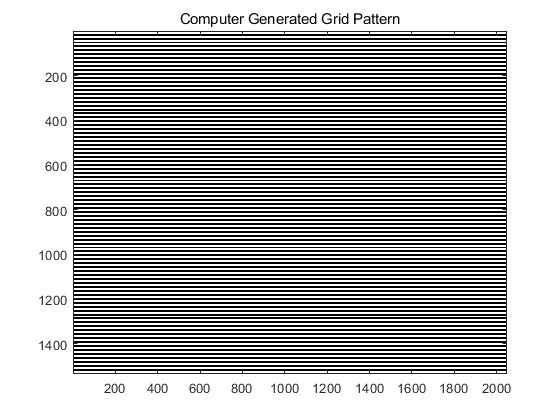

displayFig(pattern, 'Computer Generated Grid Pattern');

Display the captured image, which is acquired by projecting the grid on the curve surface object.

figCapturedPath = char("..\Experiments\Ex 3D reconstruction\pic\px.bmp")

figCapturedPath = '..\Experiments\Ex 3D reconstruction\pic\px.bmp'

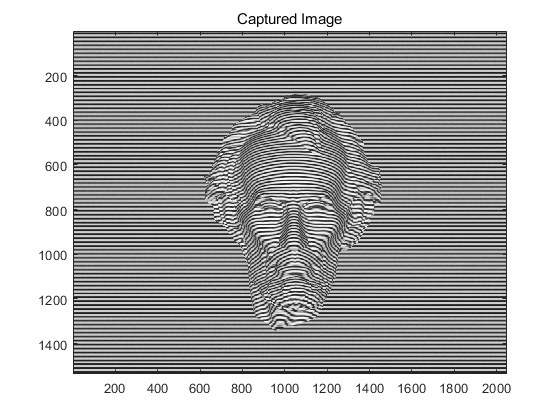

figCaptured = imread(figCapturedPath);
figCaptured = rgb2gray(figCaptured);
figCaptured = mat2gray(figCaptured, [0, 255]);
displayFig(figCaptured, 'Captured Image');

    Then, we have four more phase shifted image to digitally generate.

- The zero phase shift: we just impose computer generated grid on the captured image.

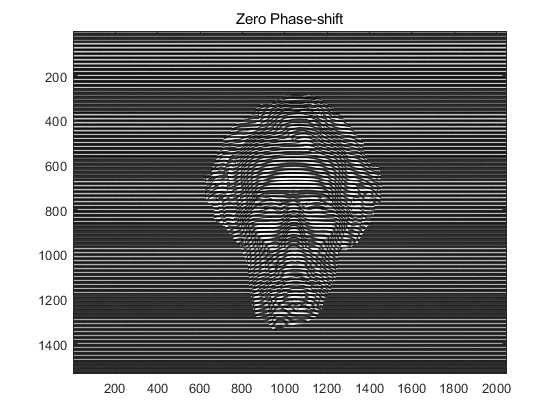

figZeroPS = figCaptured .* pattern;
displayFig(figZeroPS, "Zero Phase-shift");

-  Shift the computer generated grid with the phase pi  and superimpose on the captured frame.

patternPiPS = generatePattern(2048, 1536, 50, 200, 6, 3, 1);

Pattern ---- w2048_h1536_g50_200_wl6_p3.00_B.bmp is already generated!


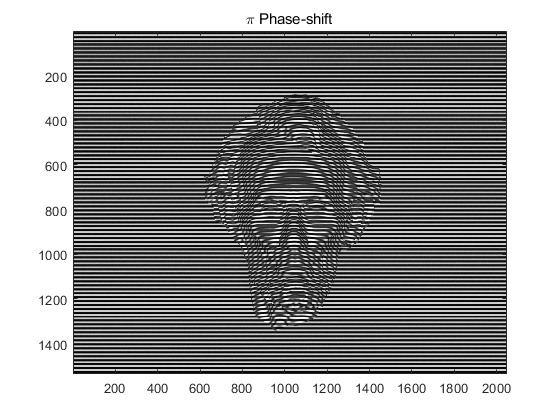

figPiPS = patternPiPS .* figCaptured;
displayFig(figPiPS, '\pi Phase-shift')

- Shift and impose the grid by the smallest phase \delta of a pixel. in our case, \delta = 2\pi / 6;                                                                                                                                                                                                                                                                                                                                 

patternDeltaPS = generatePattern(2048, 1536, 50, 200, 6, 1, 1);

Pattern ---- w2048_h1536_g50_200_wl6_p1.00_B.bmp is already generated!


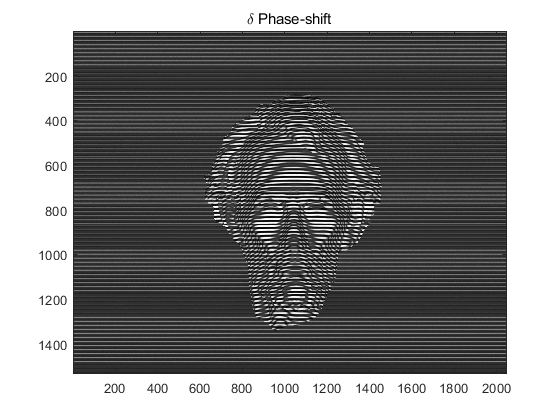

figDeltaPS = patternDeltaPS .* figCaptured;
displayFig(figDeltaPS, '\delta Phase-shift')

- Shift the gird with phase of \delta + \pi and superimpose. 

patternDeltaPiPS = generatePattern(2048, 1536, 50, 200, 6, 4, 1);

Pattern ---- w2048_h1536_g50_200_wl6_p4.00_B.bmp is already generated!


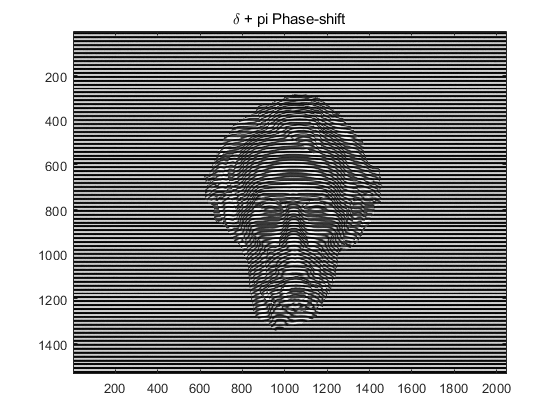

figDeltaPiPS = patternDeltaPiPS .* figCaptured;
displayFig(figDeltaPiPS, '\delta + pi Phase-shift');

Above are the four frames we generated to produce a great phase map. Then we can remove the grid in each frame to generate the phase maps.

We can also use digitalMorieSuperImpose function to generate the four figures at once.

Pattern ---- w_h1536_g50_200_wl6_p0.00_B.bmp is already generated!
Pattern ---- w_h1536_g50_200_wl6_p3.00_B.bmp is already generated!
Pattern ---- w_h1536_g50_200_wl6_p1.00_B.bmp is already generated!
Pattern ---- w_h1536_g50_200_wl6_p4.00_B.bmp is already generated!
Figure on ..\Experiments\Ex 3D reconstruction\pic\p0.bmp is generated.
Figure on ..\Experiments\Ex 3D reconstruction\pic\p3.bmp is generated.
Figure on ..\Experiments\Ex 3D reconstruction\pic\p1.bmp is generated.
Figure on ..\Experiments\Ex 3D reconstruction\pic\p4.bmp is generated.


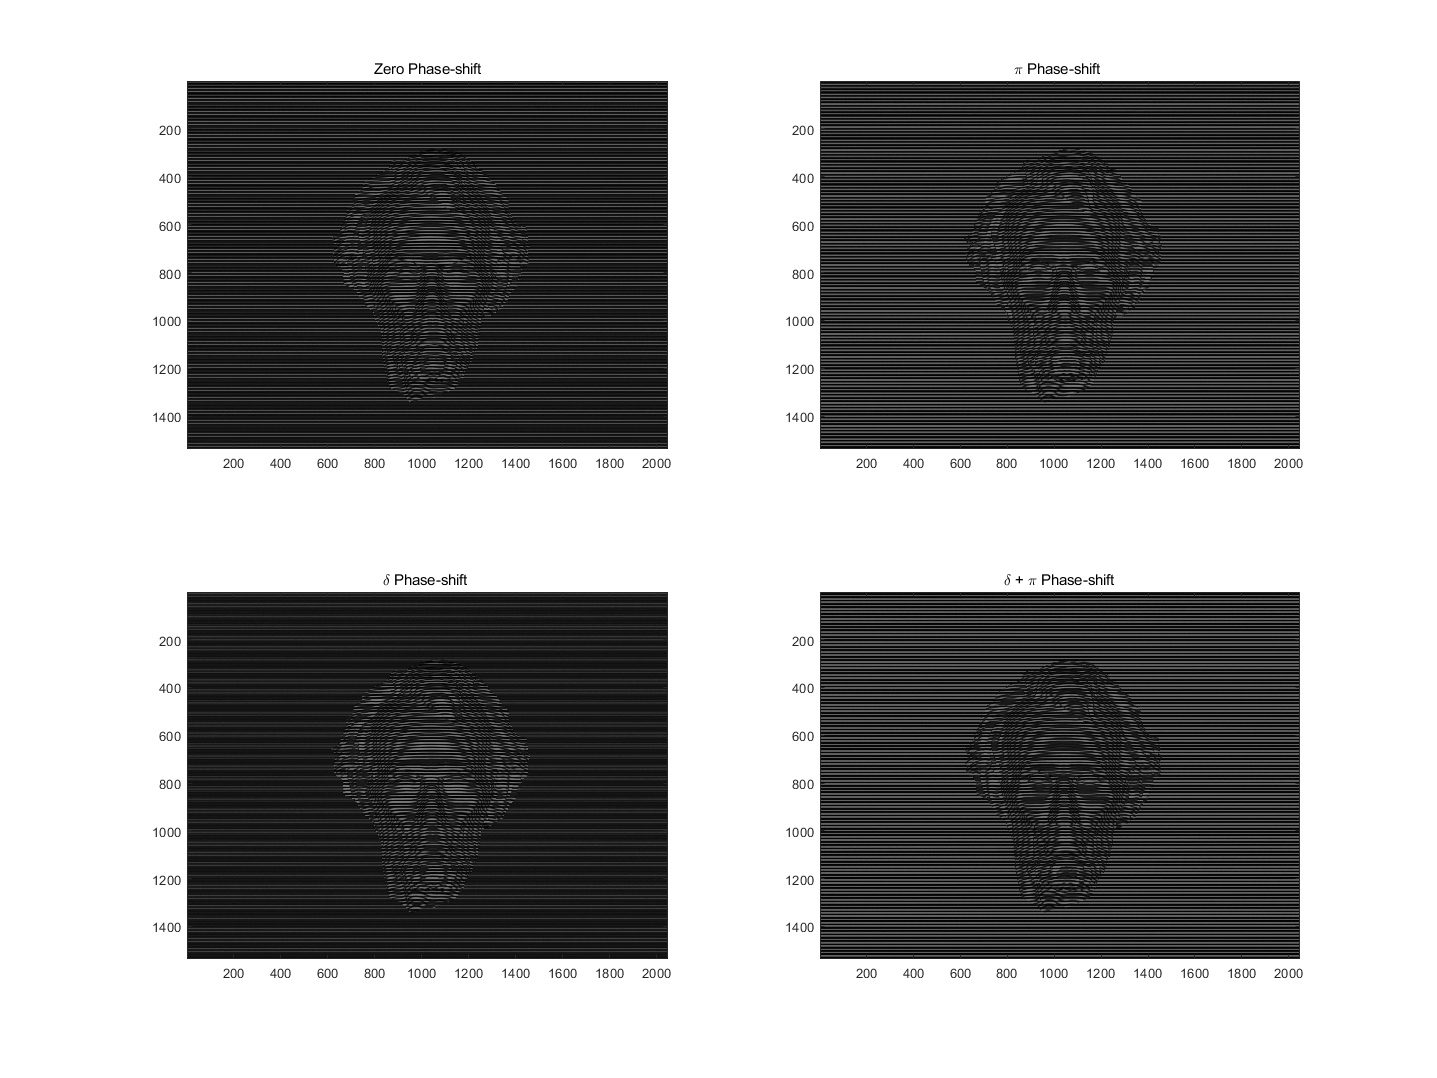

[fig0, fig1, fig2, fig3] = digitalMorieSuperimpose(figCapturedPath, patternPath, 1, true);

However, I will stick to the previous "figZeroPS" naming strategy. Then we can extract the morie patterns.Frist we will look at the last frame, the frame with \delta  + \pi phase shift. Our goal is to find best hyperparameters for optimizing the FFT-SWT grid removal method.